**4. Sabendo que um processo de fabrico produz 30% de peças defeituosas e considerando a variável aleatória X, representativa do número de peças defeituosas numa amostra de 5 peças tomadas aleatoriamente, obtenha:**

**(a)** Por simulação:

**i.** estimativa para a função massa de probabilidade de X;

experiencias_a = rand(5, 1e6);
pecas_defeituosas = sum(experiencias_a_i < 0.3);
prob_0 = sum(pecas_defeituosas == 0)/1e6

prob_0 = 0.1682

prob_1 = sum(pecas_defeituosas == 1)/1e6

prob_1 = 0.3599

prob_2 = sum(pecas_defeituosas == 2)/1e6

prob_2 = 0.3085

prob_3 = sum(pecas_defeituosas == 3)/1e6

prob_3 = 0.1328

prob_4 = sum(pecas_defeituosas == 4)/1e6

prob_4 = 0.0282

prob_5 = sum(pecas_defeituosas == 5)/1e6

prob_5 = 0.0024

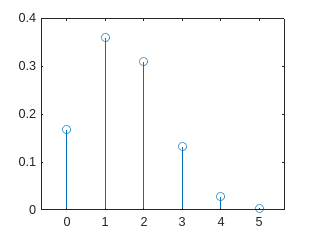


x = 0:5;
prob_x = [prob_0, prob_1, prob_2, prob_3, prob_4, prob_5];
stem(x, prob_x)

**ii.** o gráfico representativo da função distribuição acumulada de probabilidades de X;

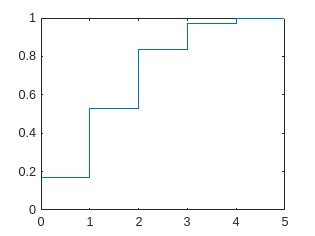

stairs(x, cumsum(prob_x))

**iii.** estimativa para probabilidade de, no máximo, 2 das peças de uma amostra serem defeituosas;

prob_iii = sum(pecas_defeituosas <= 2)/1e6

prob_iii = 0.8366

**(b)** Analiticamente:

**i. **a função distribuição acumulada de X;

**ii.** a probabilidade de, no máximo, 2 das peças de uma amostra serem defeituosas.

P(no maximo 2) = P(0) + P(1) + P(2) = ...